clc;clear;
%建立符号变量a(发展系数)和b(灰作用量)
syms a b;
c = [a b]';

%原始数列 A
A = [13635, 13847, 13978, 13922, 13921, 14240, 14309, 13976, 14005];
n = length(A);

%对原始数列 A 做累加得到数列 B
B = cumsum(A);

%对数列 B 做紧邻均值生成
for i = 2:n
    C(i) = (B(i) + B(i - 1))/2; 
end
C(1) = [];

%构造数据矩阵 
B = [-C;ones(1,n-1)];
Y = A; Y(1) = []; Y = Y';

%使用最小二乘法计算参数 a(发展系数)和b(灰作用量)
c = inv(B*B')*B*Y;
c = c';
a = c(1); b = c(2);

%预测后续数据
F = []; F(1) = A(1);
for i = 2:(n+10)
    F(i) = (A(1)-b/a)/exp(a*(i-1))+ b/a;
end

%对数列 F 累减还原,得到预测出的数据
G = []; G(1) = A(1);
for i = 2:(n+10)
    G(i) = F(i) - F(i-1); %得到预测出来的数据
end

disp('预测数据为：');

预测数据为：


G

G = 	1.0e+04 *

    1.3635    1.3918    1.3948    1.3979    1.4009    1.4040    1.4070    1.4101    1.4132    1.4163    1.4194    1.4224    1.4255    1.4287    1.4318    1.4349    1.4380    1.4411    1.4443


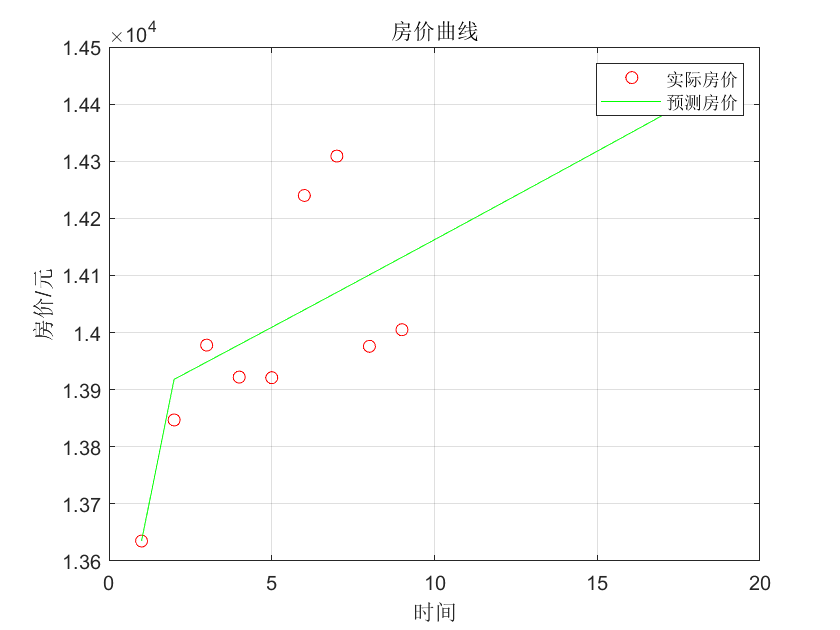


%模型检验

H = G(1:10);








%绘制曲线图
t1 = 1:9;
t2 = 1:19;

plot(t1, A,'ro'); hold on;
plot(t2, G, 'g-');
xlabel('时间'); ylabel('房价/元');
legend('实际房价','预测房价');
title('房价曲线');
grid on;